dir_path = "C:\Users\Silviu\Desktop\facultate\PI_P\pi-p-proiect-healthhackers\valid_metadata\statistici\VALID_";
data_path = "C:\Users\Silviu\Desktop\facultate\PI_P\pi-p-proiect-healthhackers\valid_metadata\training_metadata_valid.csv";
data = readtable(data_path);
data

data = 1104×14 table
     participant_id      age        sex          study_site        bmi             ethnicity               race       handedness      parent_1_education         parent_2_education        p_factor_fs    internalizing_fs    externalizing_fs    attention_fs
    ________________    _____    __________    _______________    _____    __________________________    _________    __________    ______________________    _________________________    ___________    ________________    ________________    ____________

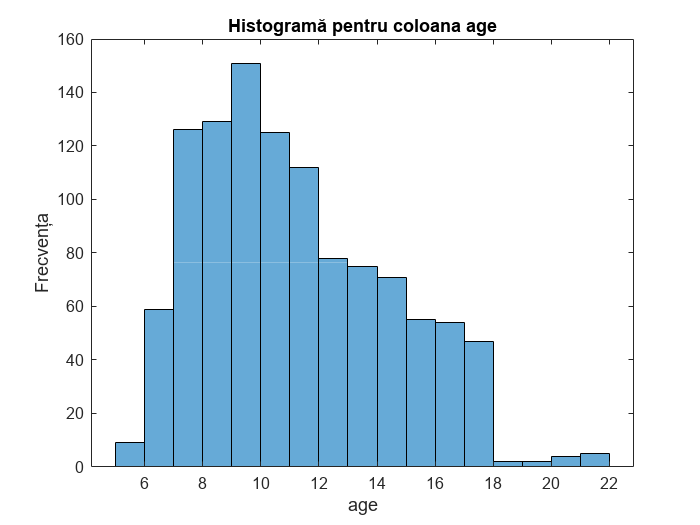

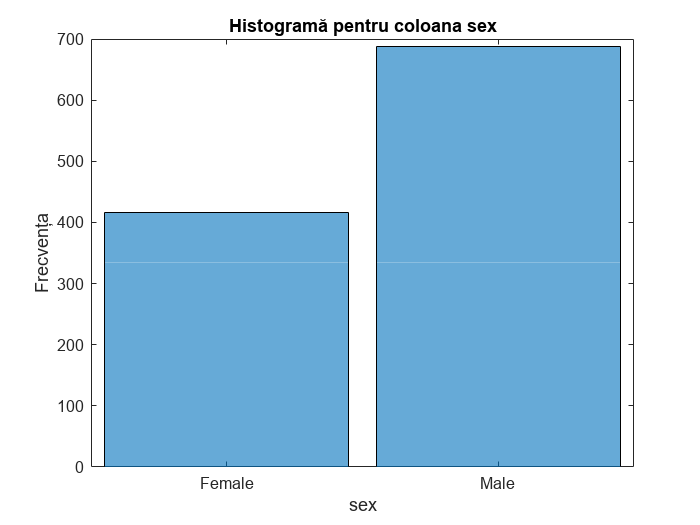

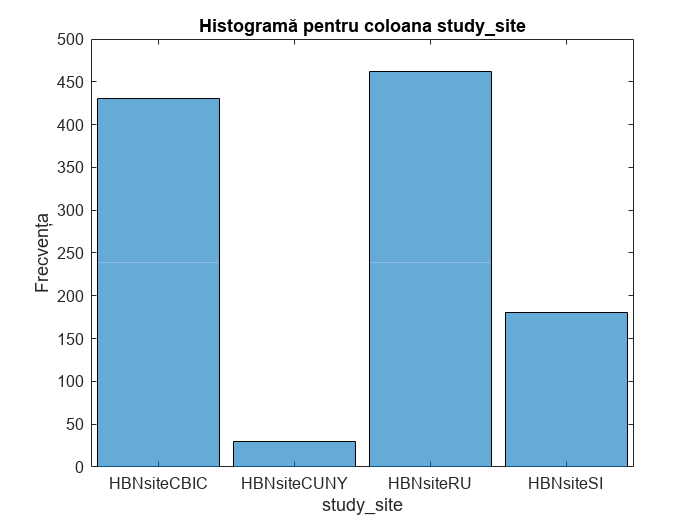

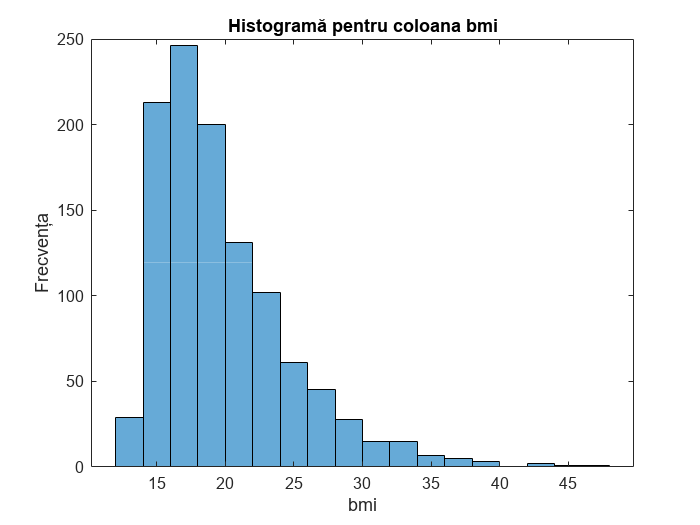

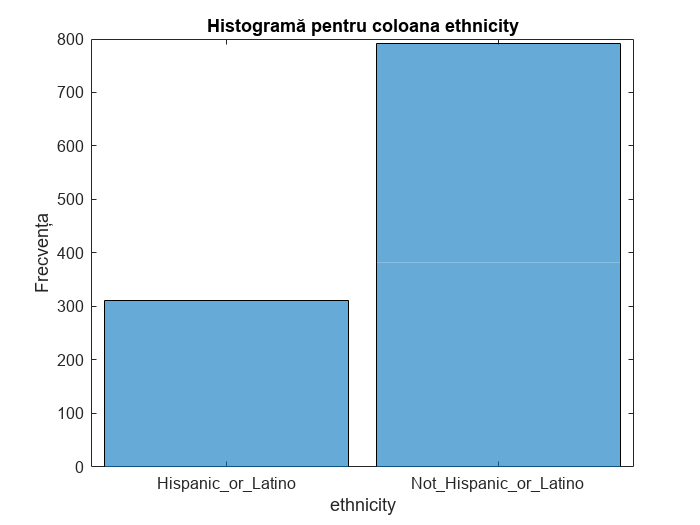

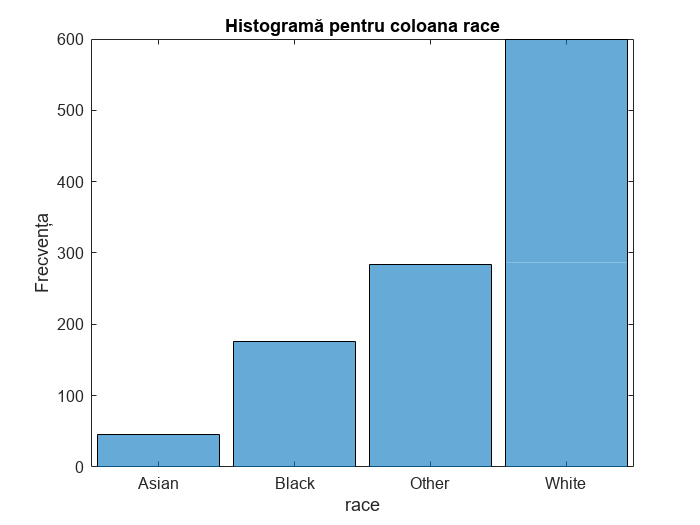

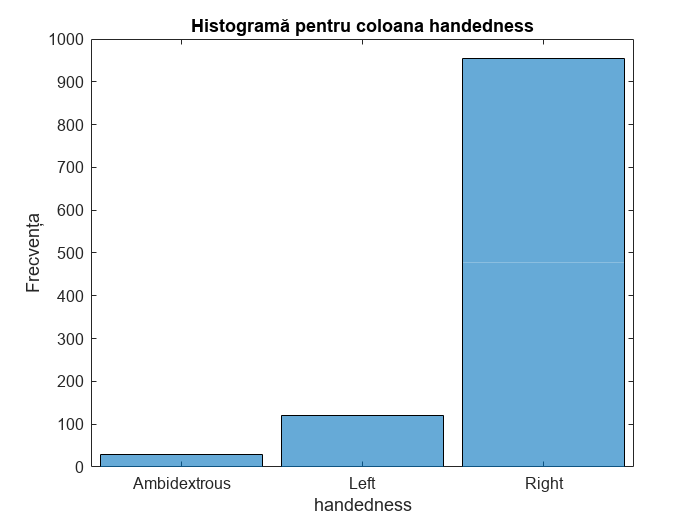

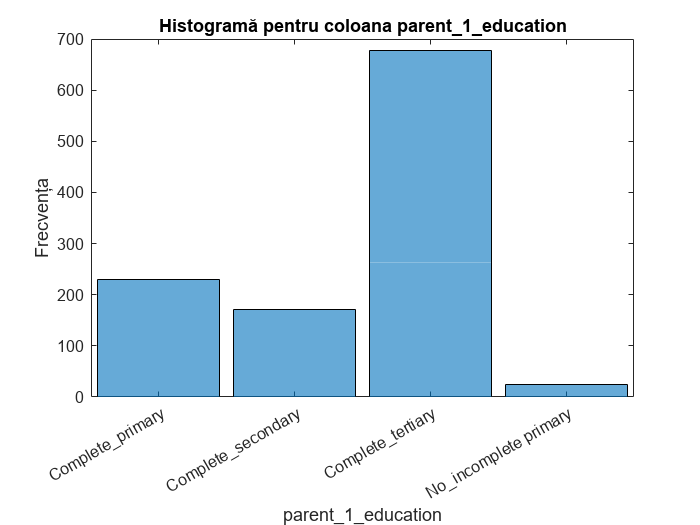

% Numărul de coloane în tabelul data
numColumns = width(data);

% Parcurge fiecare coloană și verifică tipul acesteia
for i = 2:numColumns
    
    if isstring(data{:, i}) || iscellstr(data{:, i}) || iscategorical(data{:, i})
        % Convertim coloana la variabilă categorială pentru frecvență
        dataCategorical = categorical(data{:, i});
        
        % Calculăm frecvențele fiecărei valori unice
        figure;
        h = histogram(dataCategorical); % Utilizează histogram pentru variabile categoriale
        hold on;
        title(['Histogramă pentru coloana ', data.Properties.VariableNames{i}], 'Interpreter','none');
        xlabel(data.Properties.VariableNames{i}, 'Interpreter','none');
        ylabel('Frecvența');    
        set(gca, 'TickLabelInterpreter', 'none');
        hold off;
        saveas(gcf, dir_path + data.Properties.VariableNames{i} + '.png');
    elseif isnumeric(data{:, i})
        % Dacă este coloană numerică, creăm histogramă numerică
        numericData = data{:, i};
        nanCount = sum(isnan(numericData)); % Număr de valori NaN
        
        % Elimină valorile NaN pentru a le reprezenta separat
        numericData = numericData(~isnan(numericData));
        
        % Creează histogramă pentru valorile numerice
        figure;
        histogram(numericData);
        hold on; % Reține graficul pentru a adăuga frecvența NaN
        
        % Adaugă o bară pentru NaN-uri
        if nanCount > 0
            bar(max(numericData) + 1, nanCount, 'FaceColor', 'r'); % Poziționează bara în afara domeniului numeric
            legend('Valori numerice', 'NaN');
            xticks([xticks, max(numericData) + 1]); % Adaugă un tick pentru NaN
            x = xticklabels;
            x{end} = 'NaN';
            xticklabels(x); % Etichetă pentru NaN
           
            
        end
        
        title(['Histogramă pentru coloana ', data.Properties.VariableNames{i}], 'Interpreter','none');
        xlabel(data.Properties.VariableNames{i}, 'Interpreter','none');
        ylabel('Frecvența');
        hold off;
        saveas(gcf, dir_path + data.Properties.VariableNames{i} + '.png');
    end
    
end

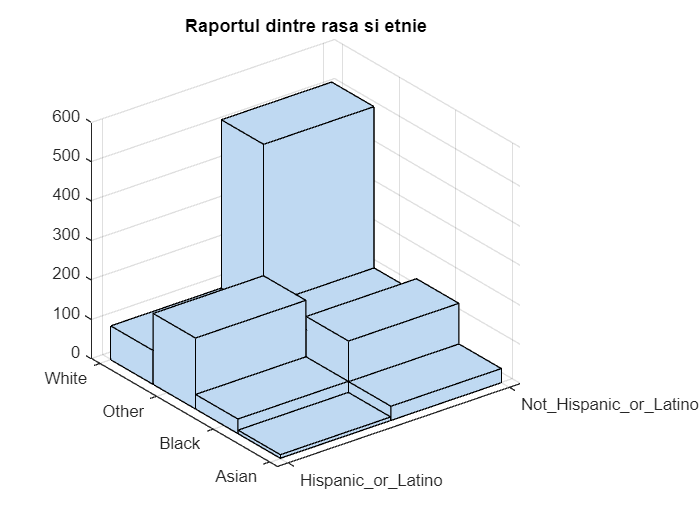

x = categorical(data{:, 'ethnicity'});
y = categorical(data{:, 'race'});
x_val = double(x);
y_val = double(y);
hist3([x_val, y_val], [2, 4]);
xticks(1:2)
title('Raportul dintre rasa si etnie')
set(gca, 'TickLabelInterpreter', 'none');
set(gca, 'XTickLabel', categories(x));
set(gca, 'YTickLabel', categories(y));
saveas(gcf, dir_path + 'Rap_etnie_rasa.png');

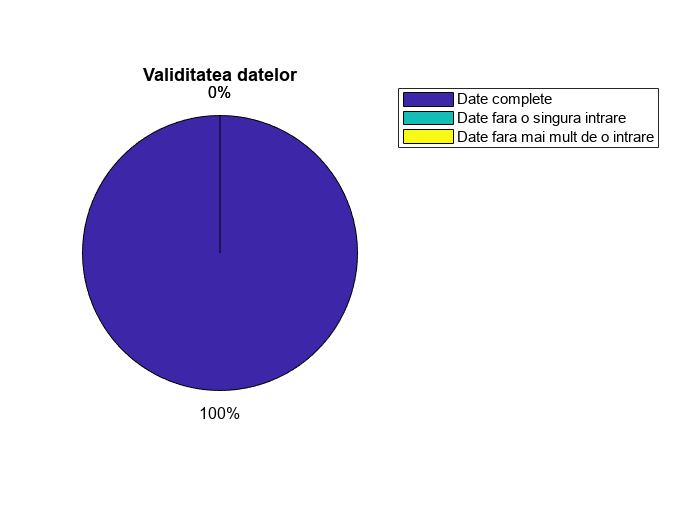

numColumns = width(data);
numRows = height(data);
numP = numRows;

validData = zeros(numRows, numColumns);

% Parcurge fiecare coloană și verifică tipul acesteia
for i = 1:numColumns
    col = data{:, i};
    if isstring(col) || iscellstr(col) || iscategorical(col)
        validData(:, i) = ~strcmp(col, 'NA');
    elseif isnumeric(col)
        validData(:, i) = ~isnan(col);
    end
end

numValidP = sum(all(validData, 2));
numNaRows = sum(validData(:, :) == 0, 2);
numNa1P = sum(numNaRows(:, :) == 1, 1);
numNa2P = numP - numValidP - numNa1P;
figure;
pie([numValidP, numNa1P, numNa2P]);
title('Validitatea datelor')
legend('Date complete', 'Date fara o singura intrare', 'Date fara mai mult de o intrare', 'Location','bestoutside');
saveas(gcf, dir_path + 'Validitate_date.png');